## TS2

P1

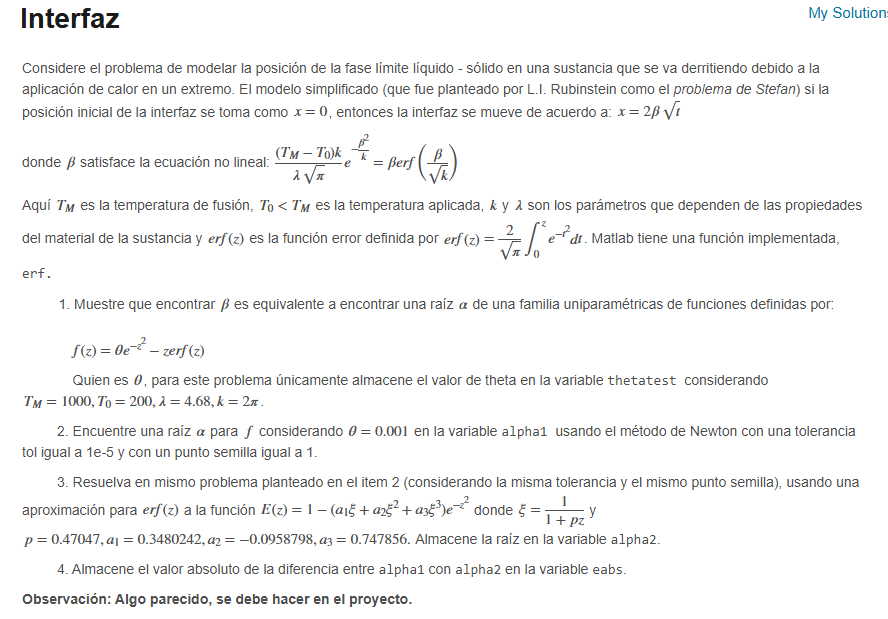

format long
Tm=1000; T0=200; lbda=4.68; k=2*pi;
thetatest=(((Tm-T0)*k)/(lbda*sqrt(pi)))/sqrt(k)

thetatest =      2.417459080979650e+02


p=0.47047;
a1=0.3480242;
a2=-0.0958798;
a3=0.747856;

f=@(x) 0.001*exp(-x.^2)-x*erf(x)

f = function_handle with value:
    @(x)0.001*exp(-x.^2)-x*erf(x)




alpha1=newton(f,1,1e-5)

alpha1 =    1.000000000000000
   0.330708437254352
   0.160720975911623
   0.082469385491418
   0.046533823119648
   0.032777818392692
   0.029899446701883
   0.029761096707911
   0.029760775518462
   0.029760775516730



f2=@(x) 0.001*exp(-x.^2)-x*(1-(a1*(1/(1+p*x))+a2*(1/(1+p*x))^2+a3*(1/(1+p*x))^3)*exp(-x^2));

alpha2=newton(f2,1,1e-5)

alpha2 =    1.000000000000000
   0.330667069482944
   0.160702614686525
   0.082450709459346
   0.046519915573996
   0.032769053569997
   0.029892904423735
   0.029754766877838
   0.029754446666848
   0.029754446665127



eabs=alpha1-alpha2

eabs = 1.0e-04 *

                   0
   0.413677714077298
   0.183612250981291
   0.186760320718543
   0.139075456519269
   0.087648226950038
   0.065422781476594
   0.063298300734434
   0.063288516140396
   0.063288516034821



%%%%%%%%%función
%{
function z=newton(f,x0,tol)
syms x
df=diff(f(x));
dfu=matlabFunction(df);
error=1;
while error >tol
   x1=x0-f(x0)/dfu(x0);
   error=abs(x1-x0)/abs(x1);
   x0=x1;
end
z=x0;
end
%}

#### P2

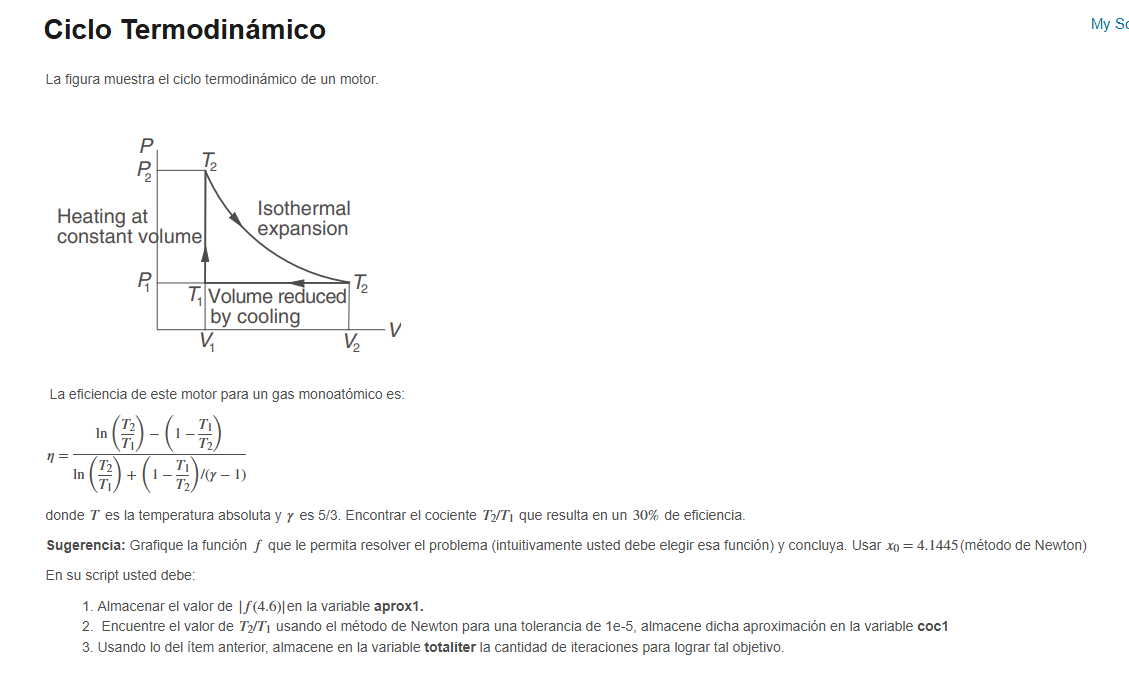

format long

gamma = 5/3;
n = 0.3;

f = @(T_ratio) (log(T_ratio)-(1-(1/T_ratio)))/(log(T_ratio)+(1-(1/T_ratio))/(gamma-1))-n;

% Evaluar f para un valor específico (ejemplo: T_ratio = 4.6)
aprox1 = abs(f(4.6))

aprox1 =    0.024645908044739



% Método de Newton para encontrar una raíz de f
x0 = 4.1445;  % Valor inicial
tol = 1e-5;   % Tolerancia
coc1 = newton(f, x0, tol)

coc1 =    4.144500000000000
   5.215390243638886
   5.407997652617871
   5.412545835820455
   5.412548241398422



% Obtener el número total de iteraciones y la raíz
totaliter = size(coc1, 1) - 1;
coc1 = coc1(end, 1)

coc1 =    5.412548241398422



% 
%{

function z = newton(f, x0, Tol)
    syms x
    % Crear la derivada simbólica a partir de la expresión f
    df = diff(f(x));  % Derivada simbólica de f
    dfu = matlabFunction(df); % Convertir la derivada simbólica en una función anónima evaluable
    
    z = x0;
    error = 1;
    while error > Tol
        x1 = x0 - f(x0) / dfu(x0); % Método de Newton
        z = [z; x1];
        error = abs(x1 - x0) / abs(x1); % Error relativo
        x0 = x1;
    end
end
%}

#### P3) Efecto Magnus

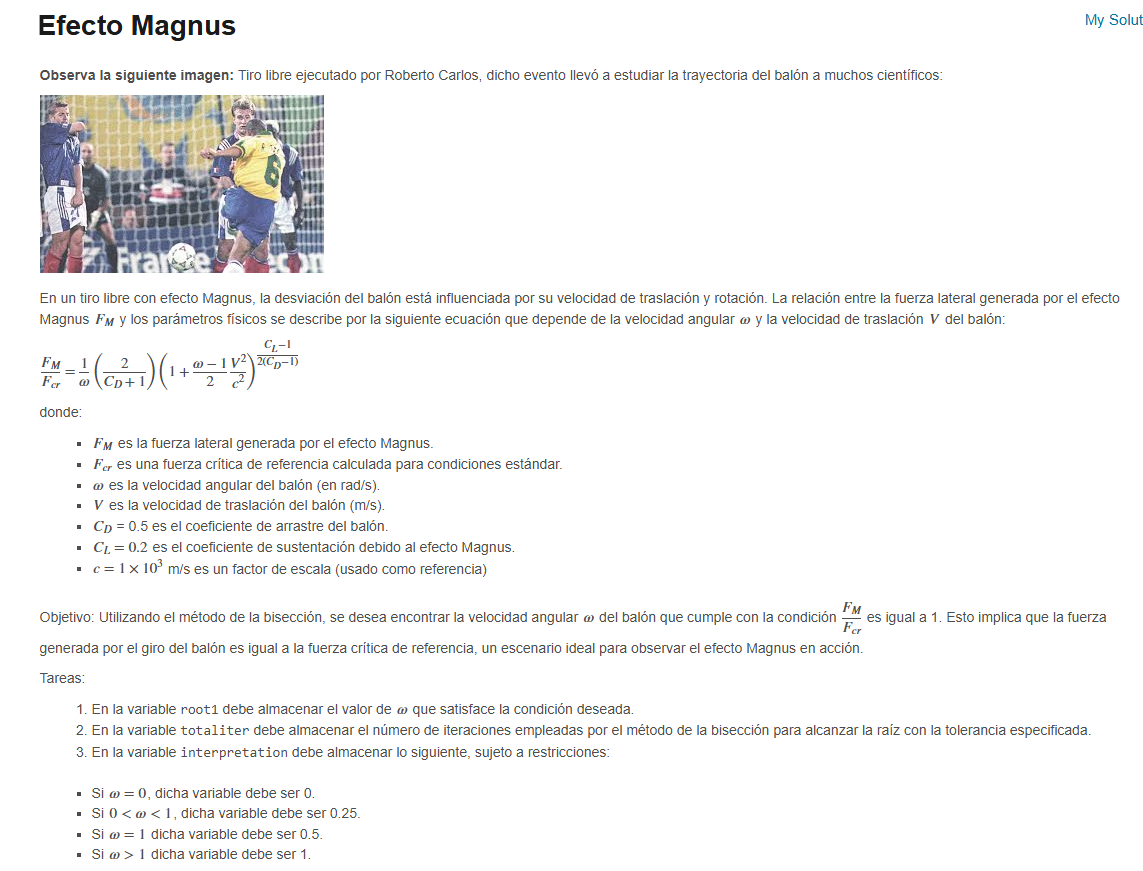


format long
%%%%Para su solucion considere tol=1e-6%%%%
% Parámetros del problema
%{
CD = 0.5;  % Coeficiente de arrastre del balón
CL = 0.2;  % Coeficiente de sustentación debido al efecto Magnus
c = 1e3;   % Factor de escala ajustado para el problema (arbitrario)
V = 30;    % Velocidad de traslación del balón (en m/s), valor supuesto

% Intervalo inicial y tolerancia
a = 0.1;    % Valor inicial del intervalo para omega (en rad/s)
b = 100;    % Valor final del intervalo para omega (en rad/s)
Tol = 1e-6; % Tolerancia para el método de bisección

f = @(w) (1/w) * ((2)/(CD+1)) * (1+((w-1)/(2))*((V^2)/(c^2)))^((CL-1)/(2*(CD-1))) - 1;

[root1, totaliter] = biseccion(f,a,b,Tol) 

interpretation = -1;
if root1 == 0
    interpretation = 0
elseif 0 < root1 && root1 < 1
    interpretation = 0.25
elseif root1 == 1
    interpretation = 0.5
elseif root1 > 1
    interpretation = 1
end

%%%%funcion biseccion modificada - usarla para el ejercicio%%%%%%

%{
function [c, totaliter] = biseccion(f, a, b, Tol)
    % Comprobar que f(a) y f(b) tengan signos opuestos
    if f(a) * f(b) >= 0
        error('f(a) y f(b) deben tener signos opuestos');
    end

    % Inicialización
    totaliter = 0;
    c = (a + b) / 2;
    error = abs(b - a) / 2;

    % Iterar hasta que el error sea menor que la tolerancia
    while error > Tol
        totaliter = totaliter + 1;
        c = (a + b) / 2;
        if f(a) * f(c) < 0
            b = c;
        else
            a = c;
        end
        error = abs(b - a) / 2;
    end
end
%}
%}

#### P4) Trayectoria de un balón de fútbol americano

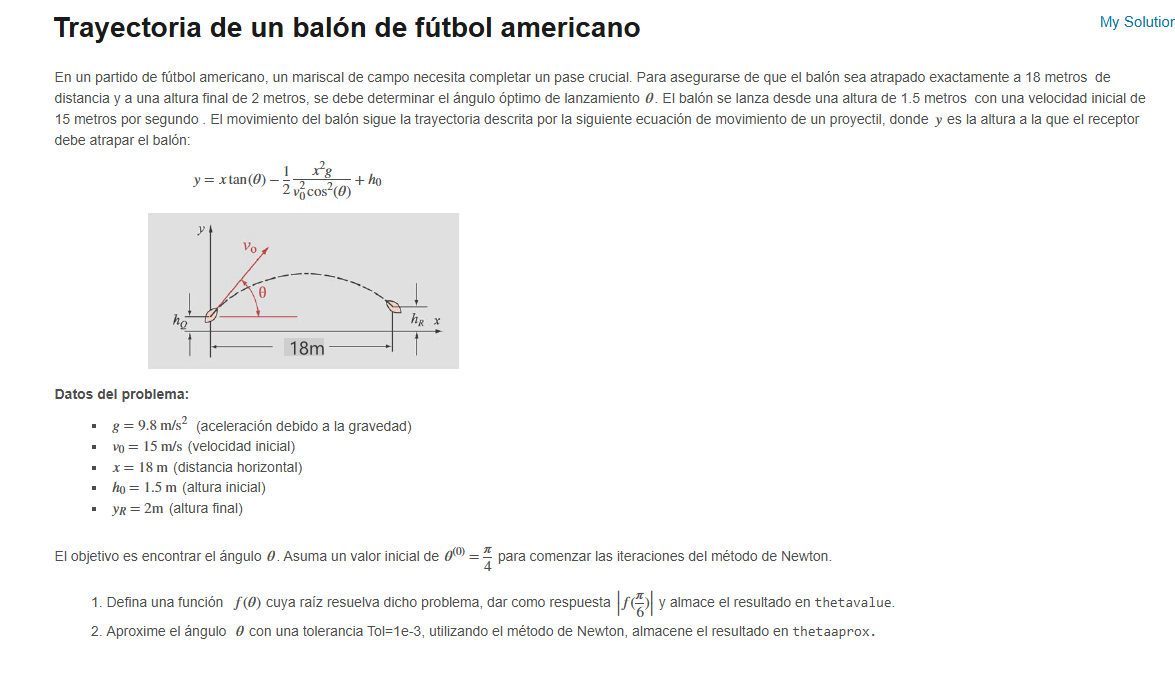

format long
g = 9.8;
v0 = 15;
x = 18;
h0 = 1.5;
yr = 2;

% Función que representa la diferencia entre la altura deseada y la calculada
f = @(theta) (x * tan(theta)) - ((1/2)*((x^(2)*g)/(v0^(2)*(cos(theta))^2))) + h0 - yr;

%1. Encuentra el valor de thetavalue
thetavalue = f(pi/6)

thetavalue =    0.484304845413265



%2. Encuentra el valor del angulo solicitado
thetaaprox = newton(f,(pi/4),1e-3)

thetaaprox =    0.785398163397448
   0.349698574920083
   0.482230120619756
   0.487204362407602
   0.487212429165331


thetaaprox = thetaaprox(end,1)

thetaaprox =    0.487212429165331



%{
function z=newton(f,x0,Tol)
    syms x
    df=diff(f(x));
    dfu=matlabFunction(df);
    z=x0;
    error=1;
    while error>Tol
        x1=x0-f(x0)/dfu(x0);
        z=[z;x1];
        error=abs(x1-x0)/abs(x1);
        x0=x1;
    end
end
%}

#### P5)

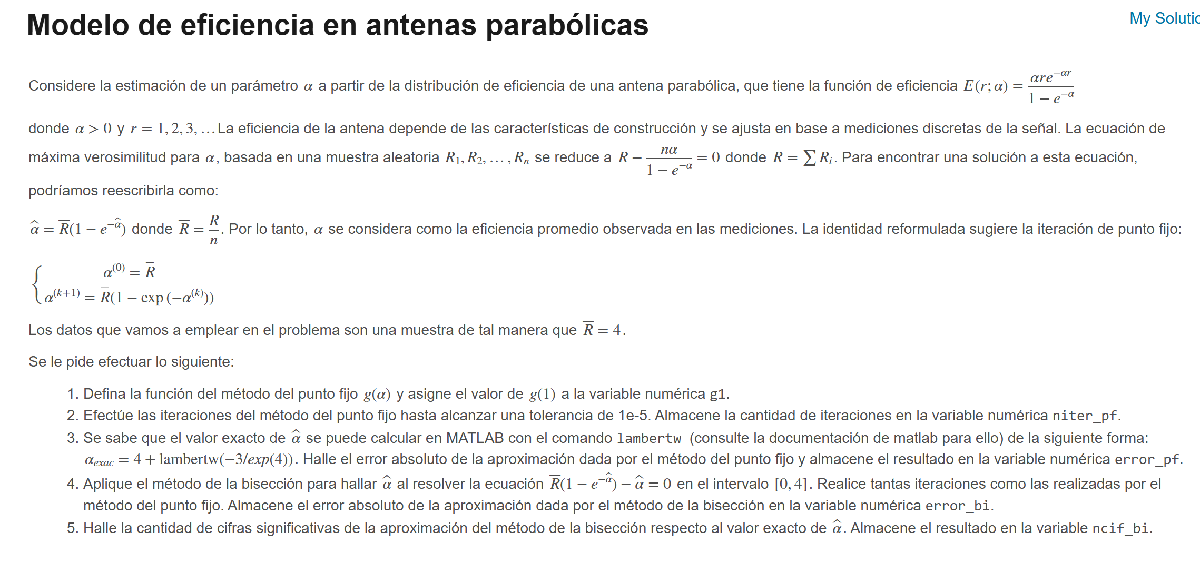

format long
R = 4;
%{
%definiendo la funcion g

g = @(alpha) R * (1 - exp(-alpha));

%asignando g(1) a la variable g1

g1 = g(1)

%aplicando el metodo del punto fijo y encontrando el numero de iteraciones
res_pf = pfijo(g, 4, 1e-5) 

niter_pf = res_pf(end, 2)
alpha_aprox_pf = res_pf(end, 1)

%encuentra el valor exacto haciendo uso del comando lambertw

alpha_real = 4 + lambertw((-3)/(exp(4))) 

error_pf = abs(alpha_real - alpha_aprox_pf)

f = @(alpha) R * (1 - exp(-alpha)) - alpha;

res_bi = biseccion(f, 0, 4, 4)

alpha_aprox_bi = res_bi(end, 3)

error_bi = abs(alpha_real - alpha_aprox_bi)

ncif_bi = 2

function z=biseccion(f,a,b,Maxiter)
    c=(a+b)/2;
    error=(b-a)/2;
    z=[a b c f(a) f(b) f(c) error];
    for k=1:Maxiter
        if f(a)*f(c)<0
            b=c;
        else
            a=c;
        end
        c=(a+b)/2;
        error=(b-a)/2;
        z=[z;a b c f(a) f(b) f(c) error];
    end
end

function z = pfijo(g,x0,tol)
    error = 1;
    iter = 0;
    z = [x0 iter];
    while error > tol
        iter = iter + 1;
        x1 = g(x0);
        z = [z; x1 iter];
        error = abs(x1-x0)/abs(x1);
        x0 = x1;
    end
end
%}

P6

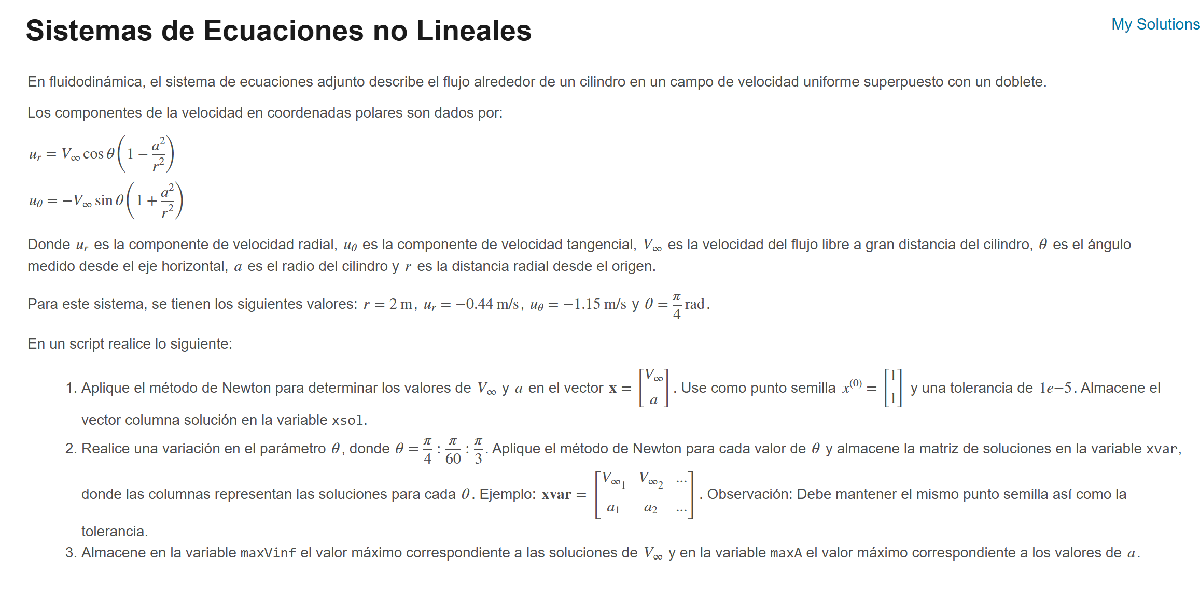

% Parámetros iniciales
r = 2; % en metros
ur = -0.44; % en m/s
utheta = -1.15; % en m/s
theta = pi/4; % en radianes

% Tolerancia y punto inicial para el método de Newton
tol = 1e-5;
maxIter = 100;
x0 = [1; 1]; % Punto inicial [Vinf; a]

% Función que representa las ecuaciones no lineales
F = @(x) [
    x(1)*cos(theta)*(1 - (x(2)^2 / r^2)) - ur; % Ecuación para ur
    -x(1)*sin(theta)*(1 + (x(2)^2 / r^2)) - utheta % Ecuación para utheta
];

% Jacobiano de las ecuaciones
J = @(x) [
    cos(theta)*(1 - (x(2)^2 / r^2)), -2*x(1)*cos(theta)*x(2)/r^2; % Derivadas parciales de la primera ecuación
    -sin(theta)*(1 + (x(2)^2 / r^2)), -2*x(1)*sin(theta)*x(2)/r^2  % Derivadas parciales de la segunda ecuación
];

% Método de Newton para encontrar [Vinf; a]
[xsol, iter] = newtonMethod(F, J, x0, tol, maxIter);

% Variación en el parámetro theta
theta_vals = linspace(pi/4, pi/3, 10); % Valores de theta entre pi/4 y pi/3
xvar = zeros(2, length(theta_vals));

for i = 1:length(theta_vals)
    theta = theta_vals(i); % Actualizar el valor de theta
    xvar(:, i) = newtonMethod(F, J, x0, tol, maxIter); % Resolver con el método de Newton
end

% Encontrar los valores máximos de Vinf y a
maxVinf = max(xvar(1, :))

maxVinf =    0.502045814642449


maxA = max(xvar(2, :))

maxA =    2.992949461465394



% Mostrar resultados

%% Función para el método de Newton


P7

format long
%Punto semilla
x0=2.5; 
y0=2 

y0 =      2


 
%si hay algo que ud. considere erroneo, borrelo
f1=@(x,y) y - (1/2) * (exp(x/2) + exp(-x/2));            % <---Complete Aquí 
f2=@(x,y) 9 * x^2 + 25 * y^2 - 225;            % <---Complete Aquí
X0=[x0;y0]

X0 =    2.500000000000000
   2.000000000000000


syms x y
F= [y - (1/2) * (exp(x/2) + exp(-x/2)); 9 * x^2 + 25 * y^2 - 225];           %<----Complete Aquí
Ffu=matlabFunction(F,'Vars',[x;y]); %borre lo que desee si considera que hay algo incorrecto
nvalue= abs(Ffu(4,4))        %<----Complete Aquí

nvalue = 1.0e+02 *

   0.002378043089164
   3.190000000000000


JF=jacobian(F);
JFinv=inv(JF);
JFinvFu=matlabFunction(JFinv, 'Vars', [x;y]); %borre lo que desee si considera que hay algo incorrecto
JFinvFu(X0(1),X0(2)); %Verificado
X1= X0 - JFinvFu(X0(1), X0(2)) * Ffu(X0(1), X0(2))          %<----Complete Aquí recordar que es vector columna

X1 =    3.138770557473749
   2.400053249136813


P8

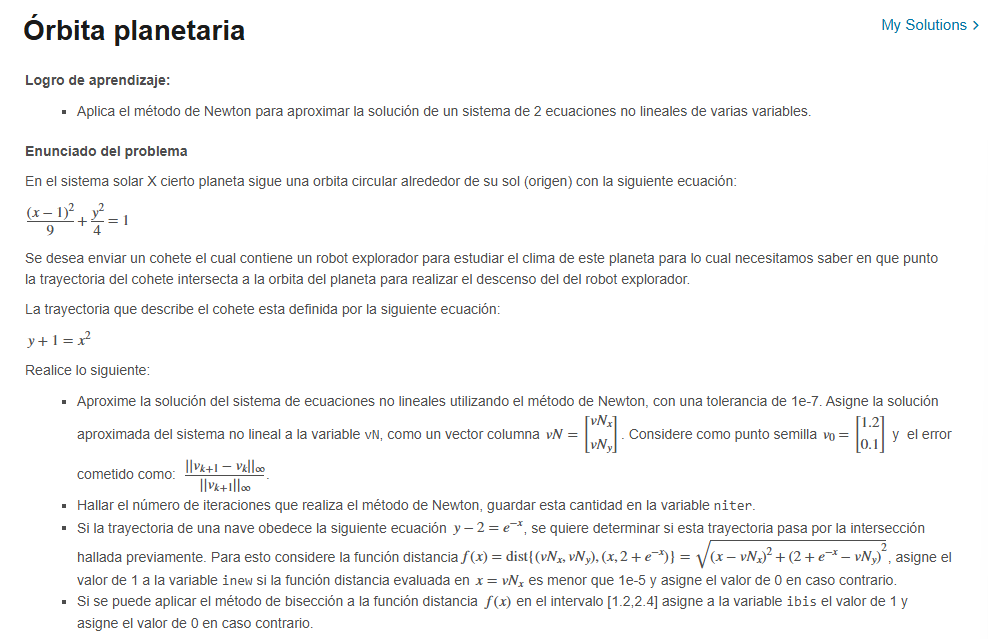

format long

Tol = 1e-7;
v0 = [1.2 0.1]'

v0 =    1.200000000000000
   0.100000000000000



F = @(x,y) [((x - 1)^2) / 9 + (y^2) / 4 - 1; y + 1 - x^2];

% 1
[sol,iter] = newtons(F,v0,Tol); 
vN= sol

vN =    1.715317707117185
   1.942314836349739


%2
niter=iter

niter =      8



% 3
distancia = @(x) sqrt((x - vN(1))^2 + (2 + exp(-x) - vN(2))^2);

if distancia(vN(1)) < 1e-5
    inew = 1 
else
    inew = 0
end

inew =      0




% 4
a = 1.2;
b = 2.4;

if distancia(a) * distancia(b) < 0
    ibis = 1 
else
    ibis = 0
end

ibis =      0




%
%{
function [x0,iter]=newtons(F,x0,Tol)
syms x y
dF = jacobian(F(x,y),[x,y]);
df_fun=matlabFunction(dF);
error=1;
z=[x0' error];
iter = 0;
while error>Tol
x1=x0-inv(df_fun(x0(1),x0(2)))*F(x0(1),x0(2));
error=norm(x1-x0,"inf")/norm(x1,"inf");
z=[z;x1' error];
x0=x1;
iter = iter +1;
end
end
%}

P9

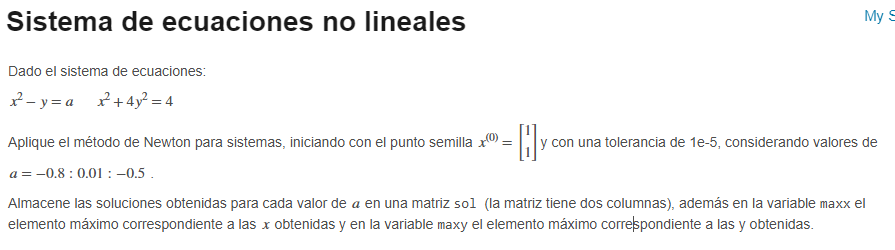

format long
a = -0.8:0.01:-0.5;
x0 = [1;1];
Tol=1e-5;
sol = zeros(length(a), 2); % Para almacenar las soluciones

%{
for i = 1:length(a)
    F = @(x,y) [x^2 - y - a(i); x^2 + 4*y^2 - 4];
    z = newtons(F, x0, Tol);
    sol(i, :) = z(end, 1:2); % Guardar la última solución (x, y)
end

maxx = max(sol(:, 1)); % El elemento máximo correspondiente a las x
maxy = max(sol(:, 2)); % El elemento máximo correspondiente a las y

%}
%{
function z=newtons(F,x0,Tol)
syms x y
dF = jacobian(F(x,y),[x,y]);
df_fun=matlabFunction(dF);
error=1;
z=[x0' error];
while error>Tol
    x1=x0-inv(df_fun(x0(1),x0(2)))*F(x0(1),x0(2));
    error=norm(x1-x0,"inf")/norm(x1,"inf");
    z=[z;x1' error];
    x0=x1;
end
end
%}

P10

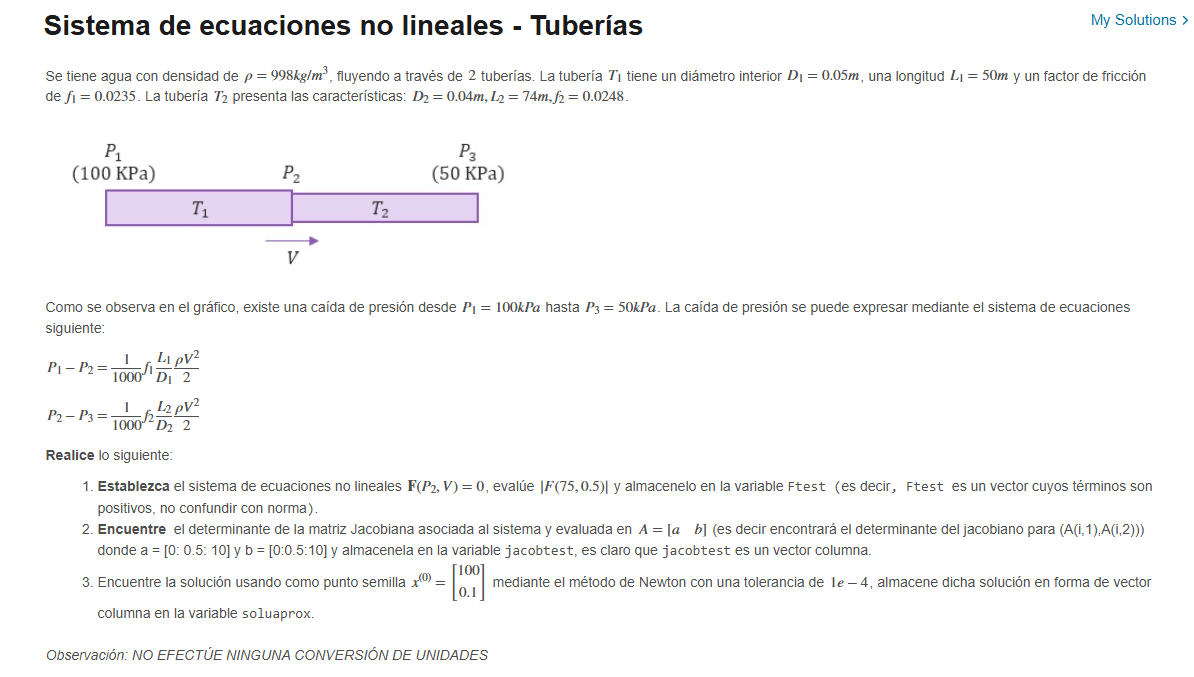

format long

rho=998;d1=0.05;L1=50;f1=0.0235;d2=0.04;

L2=74;f2=0.0248;P1=100;P3=50;

syms P2 V
F_sym = [
    P1 - P2 - (1/1000) * f1 * (L1 / d1) * (rho * V^2 / 2);
    P2 - P3 - (1/1000) * f2 * (L2 / d2) * (rho * V^2 / 2)
];

F = matlabFunction(F_sym, 'Vars', {P2, V});
J = matlabFunction(jacobian(F_sym, [P2, V]), 'Vars', {P2, V});

Ftest = F(75, 0.5)

Ftest =   22.068375000000003
  19.276470000000003



a = 0:0.5:10;
b = 0:0.5:10;

jacob = zeros(length(a), 1);
for i = 1:length(a)
    
    A = [a(i), b(i)];
    
    J_eval = J(A(1), A(2));
    
    jacob(i) = det(J_eval);
end

jacobtest = jacob

jacobtest = 1.0e+02 *

                   0
   0.346206200000000
   0.692412400000000
   1.038618600000000
   1.384824800000000
   1.731031000000000
   2.077237200000000
   2.423443400000000
   2.769649600000000
   3.115855800000000




x0 = [100; 0.1];
tol = 1e-4;
max_iter = 100;
iter = 0;

%soluaprox = newton(F, J, 100, 0.1, tol)

%{
function z = newton(F, J, P2_0, V_0, tol)

    P2 = P2_0;
    V = V_0;
    error = 1;
    iter = 0;
    
    while error > tol
        
        F_val = F(P2, V);
        J_val = J(P2, V);
        
        delta = -J_val \ F_val;
        
        P2 = P2 + delta(1);
        V = V + delta(2);
        
        error = norm(delta) / norm([P2; V]);
        
        iter = iter + 1;
    end  
    z = [P2; V];
end
%}

#### Funciones

% p1

function z=newton(f,x0,tol)
syms x
df=diff(f(x));
dfu=matlabFunction(df);
z=x0;
error=1;
while error >tol
   x1=x0-f(x0)/dfu(x0);
   z=[z;x1];
   error=abs(x1-x0)/abs(x1);
   x0=x1;
end
end

% p3 
%%%%funcion biseccion modificada - usarla para el ejercicio%%%%%%
%{
function [c, totaliter] = biseccion(f, a, b, Tol)
    % Comprobar que f(a) y f(b) tengan signos opuestos
    if f(a) * f(b) >= 0
        error('f(a) y f(b) deben tener signos opuestos');
    end

    % Inicialización
    totaliter = 0;
    c = (a + b) / 2;
    error = abs(b - a) / 2;

    % Iterar hasta que el error sea menor que la tolerancia
    while error > Tol
        totaliter = totaliter + 1;
        c = (a + b) / 2;
        if f(a) * f(c) < 0
            b = c;
        else
            a = c;
        end
        error = abs(b - a) / 2;
    end
end
%}

% p5
function z = biseccion(f, a, b, Maxiter)
    c = (a + b) / 2;
    error = (b - a) / 2;
    z = [a b c f(a) f(b) f(c) error];
    for k = 1:Maxiter
        if f(a) * f(c) < 0
            b = c;
        else
            a = c;
        end
        c = (a + b) / 2;
        error = (b - a) / 2;
        z = [z; a b c f(a) f(b) f(c) error];
    end
end


function z = pfijo(g,x0,tol)
    error = 1;
    iter = 0;
    z = [x0 iter];
    while error > tol
        iter = iter + 1;
        x1 = g(x0);
        z = [z; x1 iter];
        error = abs(x1-x0)/abs(x1);
        x0 = x1;
    end
end


p6

function [x, iter] = newtonMethod(F, J, x0, tol, maxIter)
    x = x0;
    for iter = 1:maxIter
        Fx = F(x);
        Jx = J(x);
        dx = -Jx\Fx; % Resolución del sistema lineal
        x = x + dx;

        % Comprobar convergencia
        if norm(dx) < tol
            return;
        end
    end
end


% p8 y p9
%{
function z=newtons(F,x0,Tol)
syms x y
dF = jacobian(F(x,y),[x,y]);
df_fun=matlabFunction(dF);
error=1;
z=[x0' error];
while error>Tol
    x1=x0-inv(df_fun(x0(1),x0(2)))*F(x0(1),x0(2));
    error=norm(x1-x0,"inf")/norm(x1,"inf");
    z=[z;x1' error];
    x0=x1;
end
end
%}
function [x0,iter]=newtons(F,x0,Tol)
syms x y
dF = jacobian(F(x,y),[x,y]);
df_fun=matlabFunction(dF);
error=1;
z=[x0' error];
iter = 0;
while error>Tol
x1=x0-inv(df_fun(x0(1),x0(2)))*F(x0(1),x0(2));
error=norm(x1-x0,"inf")/norm(x1,"inf");
z=[z;x1' error];
x0=x1;
iter = iter+1;
end
end